# Regular Falsi Method

**Regula Falsi method** or the **method of false position** is a numerical method for solving an equation in one unknown. It is quite similar to bisection method and is one of the oldest approaches. It was developed because the bisection method converges at a fairly slow speed. In simple terms, the method is the trial and error technique of using test ("false") values for the variable and then adjusting the test value according to the outcome.

The convergce process in the bisection  depends only on the choice of end points of the interval [a,b]. The function f(x) does not have any role in finding the point c (which is just  the mid-point of a and b).An alternative method that exploits this graphical insight is to join f (a) and f (b) by a straight line. The intersection of this line with the x axis represents an improved estimate of the root. The fact that the replacement of the curve by a straight line gives a “false position” of the root is the origin of the name, method of false position, or in Latin,** regula falsi**. It is also called the linear interpolation method.

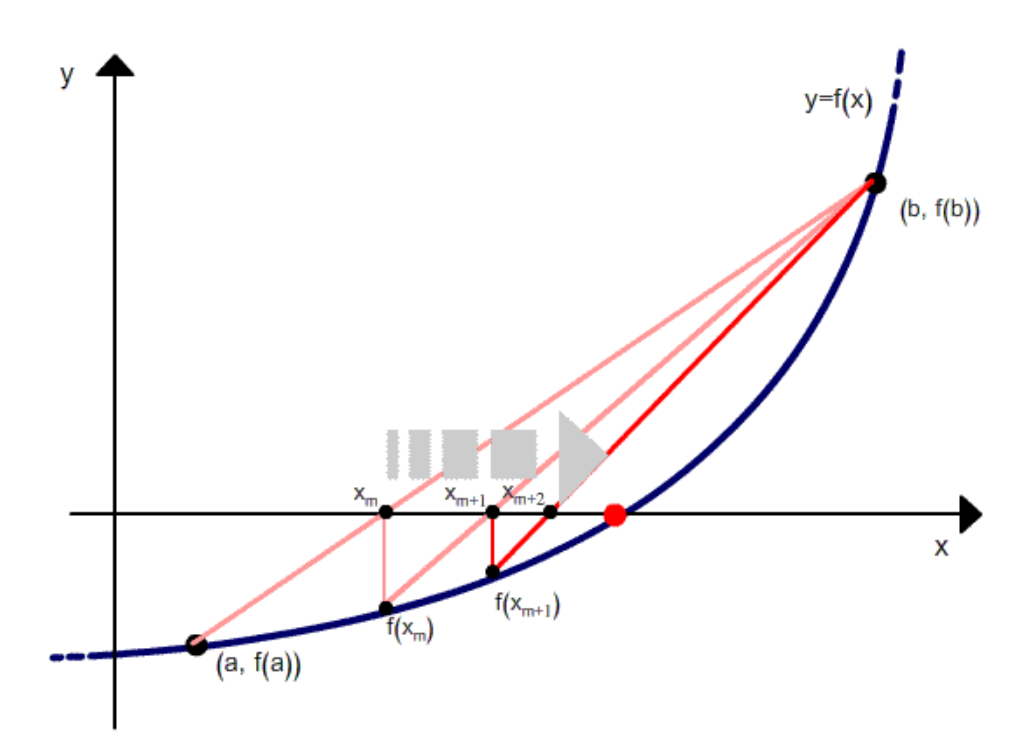

### **Converging Towards Roots:**

Bisection method used the midpoint of the interval [a, b] as the next iterate to converge towards the root of f(x). A better approximation is obtained if we find the point (c, 0) where the secant line L joining the points (a, f (a)) and (b, f (b)) crosses the x-axis. To find the value c, we write down two versions of the slope m of the line L:

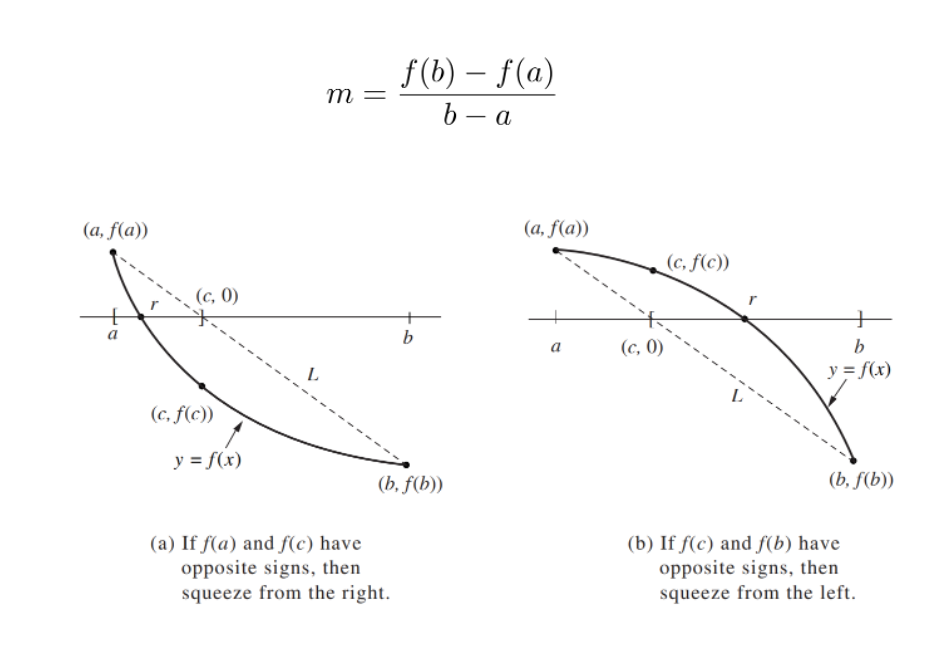

We first use points *(a, f (a)) and (b, f (b))* to get equation 1 (below), and then use the points *(c, 0) and (b, f (b))* to get equation 2 (below). Equating these two equation we get equation 3 (below) which is easily solved for c to get equation 4 (below):

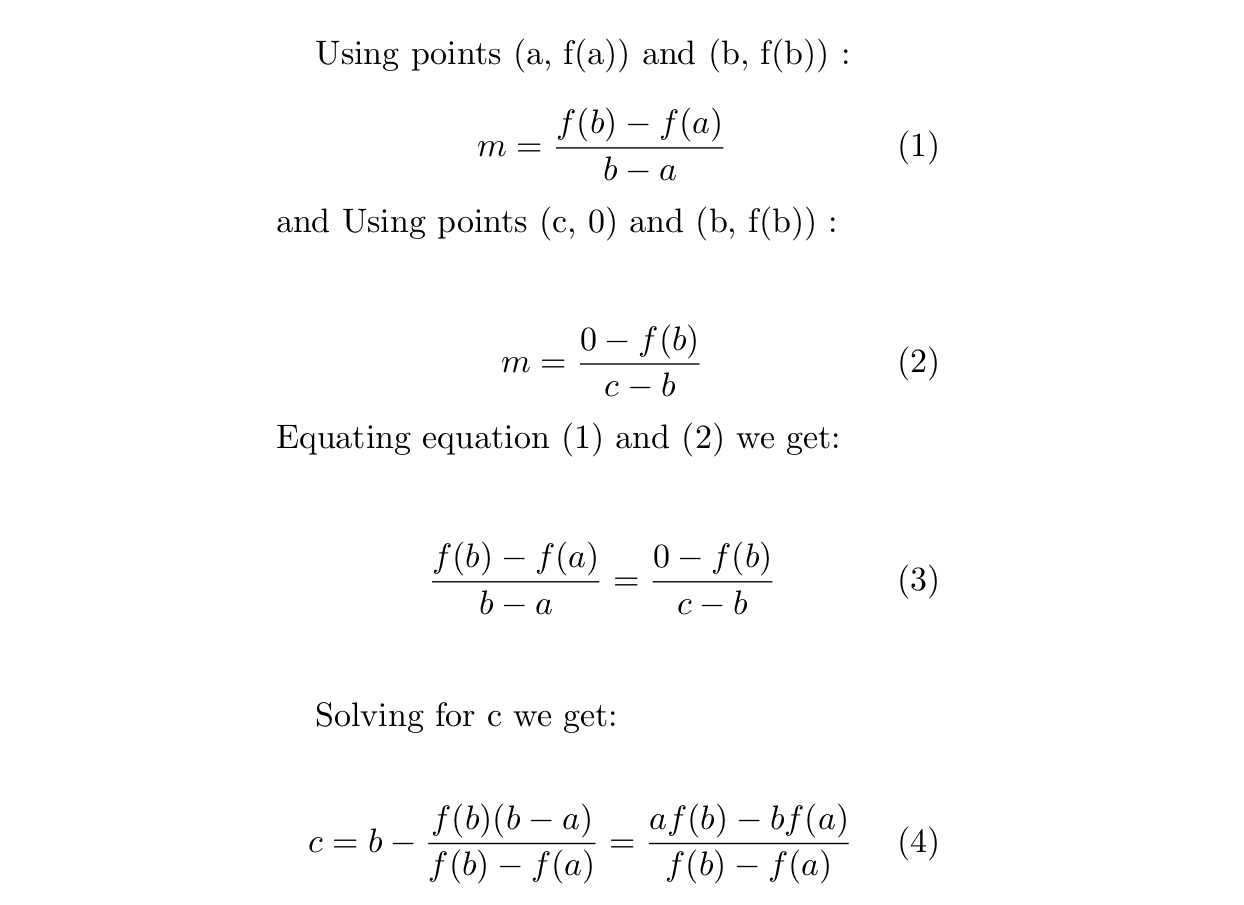

For simplicity we have consider c = $x_r$ which means the root of x.

### **Step 1 : Defining the Function **

First step of this method is to define the function and it's lower bound and upper bound which is **a** and **b. **We have to remember that the the functional value of point **a** and **b** must have to be opposite sign.For ensuring the accuracy of the root, we have to define the accuracy(**accuracy**) .

Here we will take function as input from user which will be treated as a string and stored into  **f_input** variable.Using inline function (ignoring warning )  we have turned it into a vector which can be calculated by Matlab.

Here we have defined accuracy as approximate relative error which can be representated as 

### 
$$\textrm{accuracy}=|\frac{x_r^{\textrm{new}} -x_r^{\textrm{old}} }{x_r^{\textrm{old}} }|$$


For simplification of our calculation we didnot converted the accuracy into % .So if we want 1% accuracy here the value of accuracy will be 0.001

f_input = input("Enter f(x) = ","s");           %Function of variable x
f = inline(f_input);                %using anonymous function instead of inline function
a = input ( "Value of a =");
b = input ( "Value of b =");
accuracy = input ( "Value of required accuracy  =");

### **Step 2 : Checking Functional Value at point a and b**

In this step we will use **if** statement to check that is the input value satisfies the condition of regular falsi method which is the multiplication of  functional value at point a and b will be smaller than 0.If the multiple of functional value at boundary point denies the required condition we will print a massage and use **return** statement to stop executing rest of the matlab script.

Why we will not check that, Is the  user defined roots as one of the boundary values ?  

if f(a) * f(b) > 0 
    fprintf("No roots exist within the given interval \n");
    return
end 

if (f(a) == 0 || f(b) == 0 )
    fprintf("Boundary value is one of the roots\n")
    return 
end


### **Step 3 : Initialize the values **

First we have to inititalize some required values.To start counting our number of interation, we assigned  i= 0 , and we have initialized our first $x_r^{\textrm{old}} =a\;$

i = 0;
xr_old = a ;

### **Step 4 : Let's start iteration **

- For iteration process we will use while loop as our iteration will continue untill we achieve our required accuracy.

- Next accepted root according to regula falsi is $x_r =b-\frac{f\left(b\right)\left(b-a\right)}{f\left(b\right)-f\left(a\right)}$ 

-  If f($x_r$) *f (b) < 0, there exist a root between $x_r$ and b ,so $x_r$ will be our new a.Else , f($x_r$)*f(a) <0,  so there exist a root between $x_r$ and a .so $x_r$ will be our new b.

- As first iteration is completed we will increase the value of **i** by one which is our number of iteration.

- As the value of our **a **or **b**  is changed, now we will calculate our next $x_r$ value $x_r =b-\frac{f\left(b\right)\left(b-a\right)}{f\left(b\right)-f\left(a\right)}$ and assign our previous $x_r$ value to $x_r^{\textrm{old}}$.

- As we want to print our iteration result as table, so firstly we have printed heading of the table just only when the value of iteration is 1. Then we have printed all other values of current iteration  

while abs ((xr_old-xr)/xr) > accuracy
    xr = b -(f(b)*(b-a))/(f(b)-f(a));
    if (f(xr)*f(b)<0)
        a =xr;
    else 
        b=xr;
    end
    i=i+1;
    xr_old = xr;
    xr= b -(f(b)*(b-a))/(f(b)-f(a));
    if i == 1
        fprintf("Iteration \t\t a \t\t b \t\t Xr");
    end
 
    fprintf('\n %d \t \t %f\t %f\t %f', i, a,b,xr);
end

### **Step 6 : Final Result **

After completing the iteration we will print our final result which is the latest $x_r$ Value .The data type of our result is double ,so we used %f as format specifier.

fprintf("\n \t Root of equation is %f",xr)